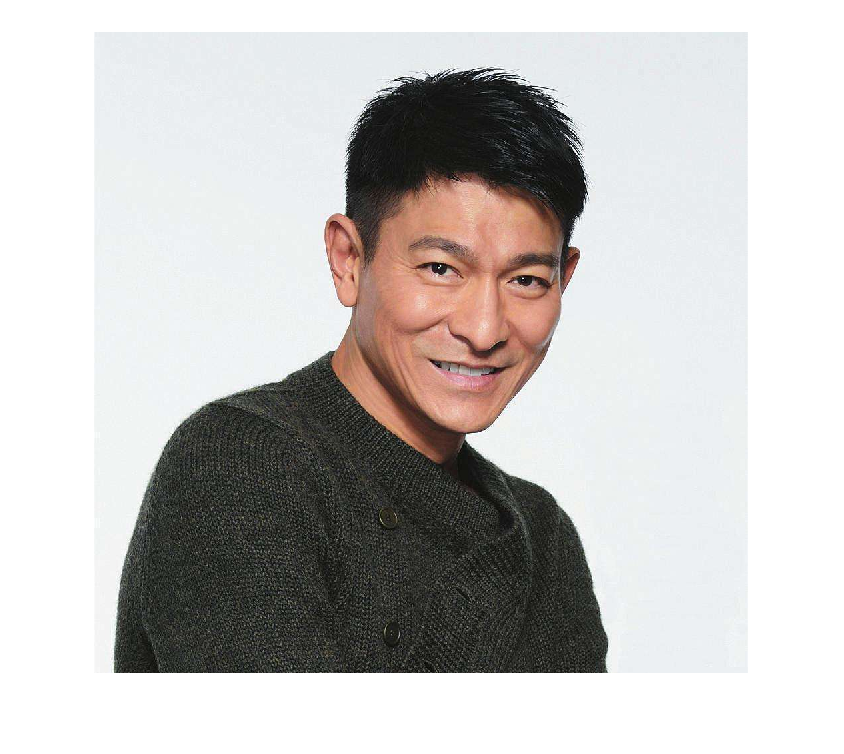

clc;clear;close all;
image_o=imread("14-刘德华.jpg");
figure;
imshow(image_o);

%基操


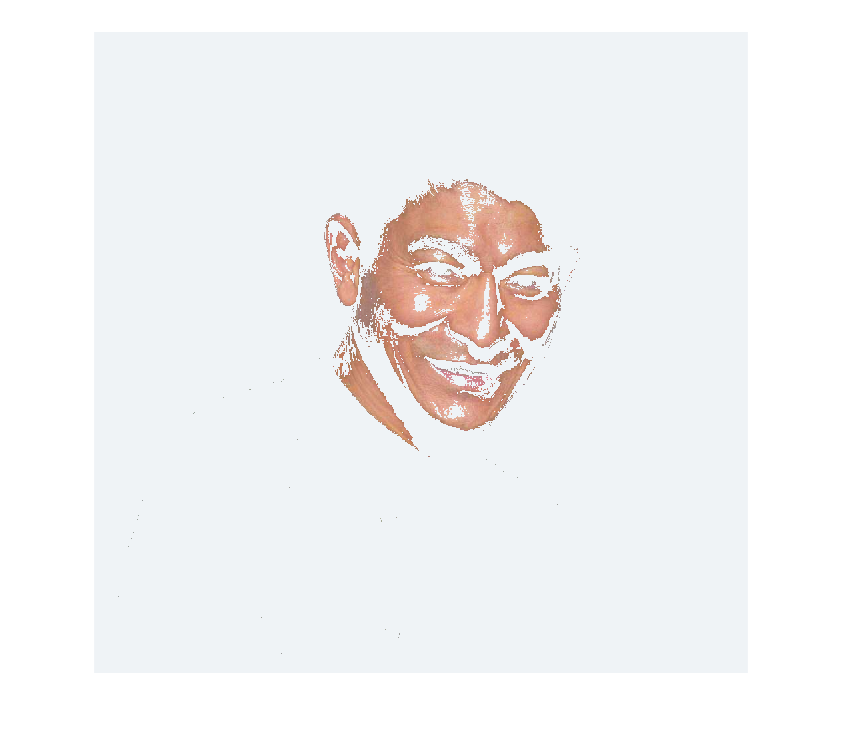

%对图像进行彩色分层操作，尽量保持面部区域色彩不变，其他区域置灰，进行显示
%经过像素检查，脸部的像素r(180-210),g(93-130),b(90-130);
image=im2double(image_o);

im_r=image(:,:,1);%分离三通道,用于检测
im_g=image(:,:,2);
im_b=image(:,:,3);

template=zeros(size(im_r));
%肤色取色
template(im_r>0.6078&im_r<0.9561&im_g>0.4654&im_g<0.9141&im_b>0.322&im_b<0.620)=1;

image(:,:,1)=image(:,:,1).*template;%提取皮肤
image(:,:,2)=image(:,:,2).*template;
image(:,:,3)=image(:,:,3).*template;

image(:,:,1)=image(:,:,1)+(1-template)*0.9373;%背景置灰
image(:,:,2)=image(:,:,2)+(1-template)*0.9529;
image(:,:,3)=image(:,:,3)+(1-template)*0.9647;

figure;
imshow(image);

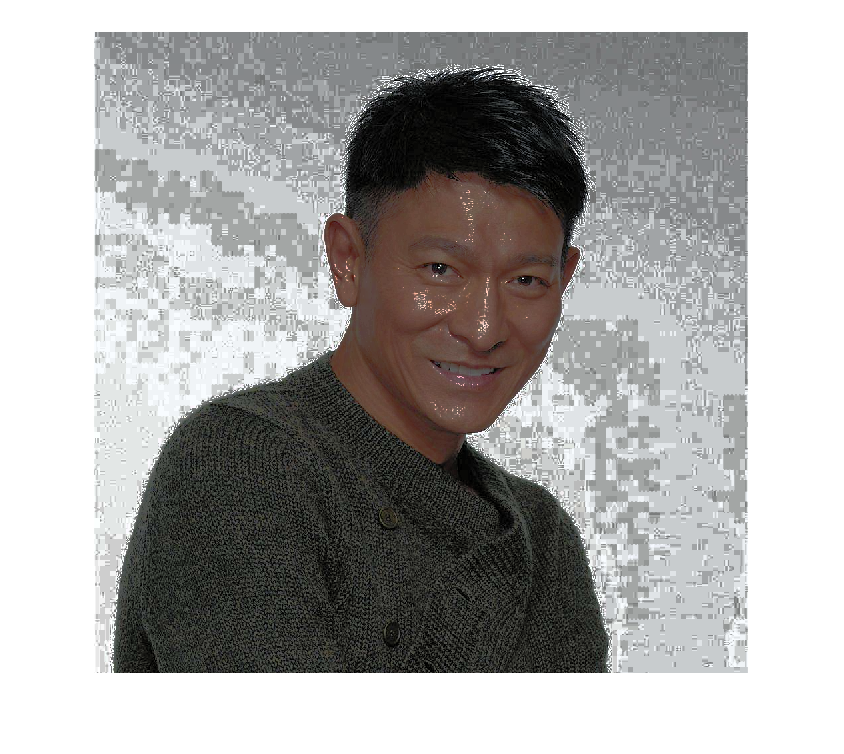

%对图像进行彩色直方图均衡化处理，显示均衡化前、后图像


image=rgb2hsv(image_o);
%image=im2double(image);

%进行均衡化
image(:,:,3)=histeq(image(:,:,3));
image=hsv2rgb(image);

%展示图像
figure;
imshow(image);